# Mosaicing

If we capture a plane and the scene reference frame is aligned to it, all the points have the same height, and thus some simplifications can be done. When the reference frame is exacly on top of the plane $\pi$, such that $M=\left[\matrix{x & y & 0 & 1}\right]^T$, we can then write


$$m \simeq PM \qquad \Longrightarrow \qquad m \simeq \left[\matrix{p_{11} & p_{12} & p_{13} & p_{14} \cr p_{21} & p_{22} & p_{23} & p_{24} \cr p_{31} & p_{32} & p_{33} & p_{34}}\right] \left[\matrix{x \cr y \cr 0 \cr 1}\right] \qquad \Longrightarrow \qquad m \simeq \left[\matrix{p_{11} & p_{12} & p_{14} \cr p_{21} & p_{22} & p_{24} \cr p_{31} & p_{32} & p_{34}}\right] \left[\matrix{x \cr y \cr 1}\right] \qquad \Longrightarrow \qquad m \simeq H \left[\matrix{x \cr y \cr 1}\right]$$


where $H$ is the **homography** that linearly maps the plane to the image, and thus is invertible.

In a stereo setup with those conditions, we could simply map the points from one image to the other using


$$m \simeq H_\ell M \qquad m' \simeq H_r M \qquad \Longrightarrow \qquad m' \simeq H_r {H_\ell}^{-1} m \qquad m \simeq H_\ell {H_r}^{-1} m'$$


where $H_\pi = H_r {H_\ell}^{-1}$ is the **homography from left to right induced by the plane **$\pi$.

This homography is easly estimated with the same method we used for the Direct Linear Transform.

addpath('../0.utils');

img1 = imread('imgs/river_1.jpg');
img2 = imread('imgs/river_2.jpg');
%
%img1 = imread('imgs/roofs_1.jpg');
%img2 = imread('imgs/roofs_2.jpg');
%
%img1 = imread('imgs/panorama_1.jpg');
%img2 = imread('imgs/panorama_2.jpg');

img1 = rgb2gray(img1);
img2 = rgb2gray(img2);

fig = figure(1); set(fig, 'Visible', 'on'), imshow(img1);
fig = figure(2); set(fig, 'Visible', 'on'), imshow(img2);

% select the correspondences
np = 8;  % 4 minimum 
m1 = zeros(3,np);
m2 = zeros(3,np);
for i=1:np
    figure(1), hold on;
    [u, v] = ginput(1);
    plot(u,v,'g*');
    m1(:,i) = [u v 1]';
    %
    figure(2), hold on;
    [u, v] = ginput(1);
    plot(u,v,'b*'); 
    m2(:,i) = [u v 1]';
end
clear u v
close(1), close(2);


% estimate the homography
H = homography(m1, m2);

% save the result
save('homography_setup.mat', 'H', 'img1', 'img2');

clear np i m1 m2 A k Vt

## Apply the warping and show the mosaic

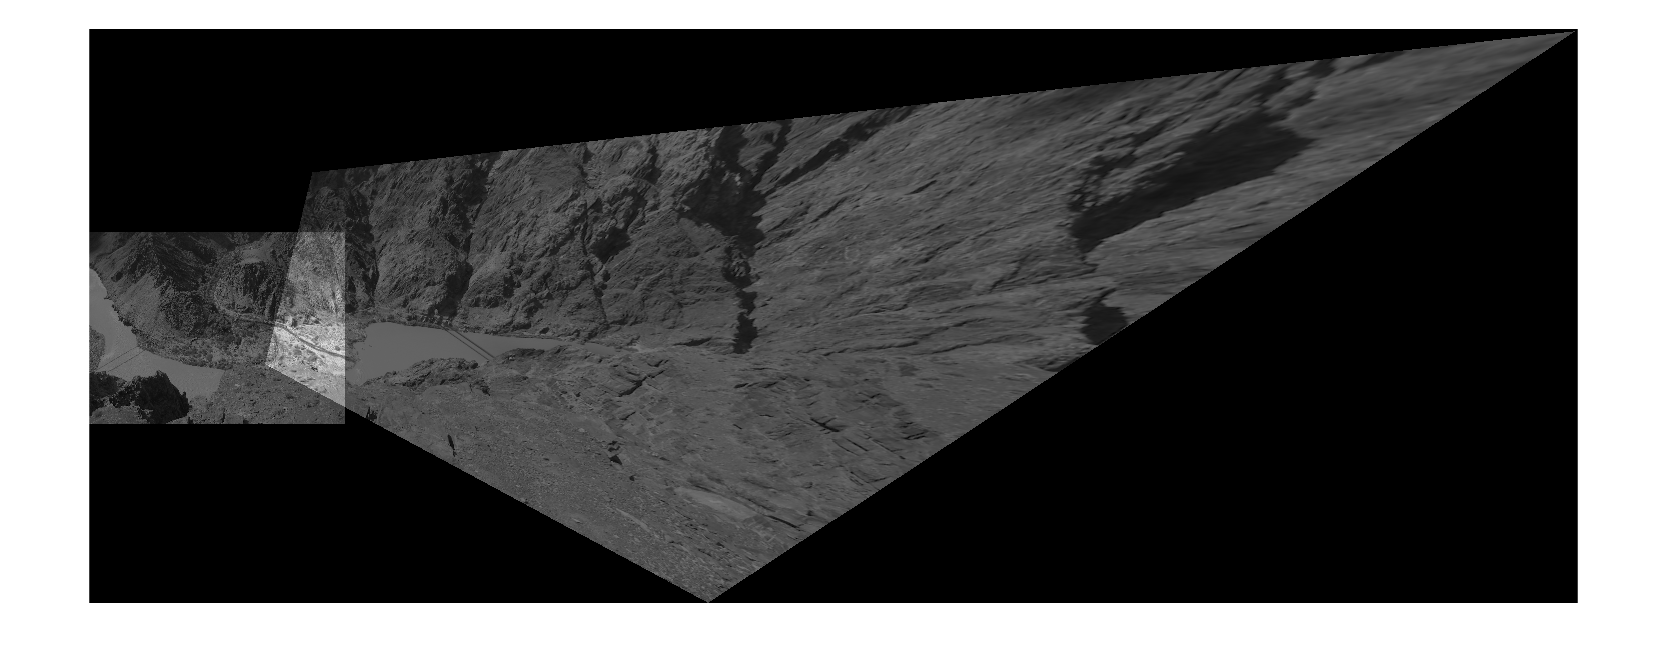

load('homography_setup.mat');

n_imgs = 2;
Hs = {eye(3), H};
imgs = {img1, img2};
bbs = zeros(4,n_imgs);

for i=1:n_imgs
    [img, bb, ~] = imwarp(imgs{i}, inv(Hs{i}), 'linear', 'valid');
    img(isnan(img)) = 0;  % replace transparency with 0
    % reorder [minx; miny; maxx; maxy] to [miny; minx; maxy; maxx]
    imgs{i} = img;
    bbs(:,i) = [bb(2); bb(1); bb(4); bb(3)];
end

% adjust mosaic bounding box
bb_mos = [min(bbs(1,:))
          min(bbs(2,:))
          max(bbs(3,:))
          max(bbs(4,:))];

% handle bottom-left global displacement
off_y = abs(bb_mos(1)); 
off_x = abs(bb_mos(2));
disp = [off_y; off_x; off_y; off_x];
bb_mos = bb_mos + disp;

mosaic = zeros(bb_mos(3)+1, bb_mos(4)+1);

clear off_y off_x bb_mos

% paste each img with the correct offset
for i=1:n_imgs
    img = imgs{i};
    bb = bbs(:,i) + disp;
    [img_y, img_x] = size(img);
    patch = zeros(size(mosaic));
    patch(bb(1)+(1:img_y), bb(2)+(1:img_x)) = img(:,:) ./ n_imgs;
    mosaic = mosaic + patch;
end
clear i img bb disp img_y img_x patch ...
    n_imgs Hs imgs bbs

figure(), imshow(uint8(mosaic));